close all
clear
clc

定义采样时刻

t = [0:0.1:2*pi]';

直接定义两个函数句柄

fh = {@sin, @cos};

第三个函数句柄由字符串变换得到

fh{3} = str2func('exp');

第四个函数句柄是定义的匿名函数

fh{4} = @(t)t.^2-4*t+1;

开始绘图

figure;
for n = 1:4
    subplot(2,2,n);

绘制波形

    plot(t,fh{n}(t));

将函数句柄转换为字符串作为标题

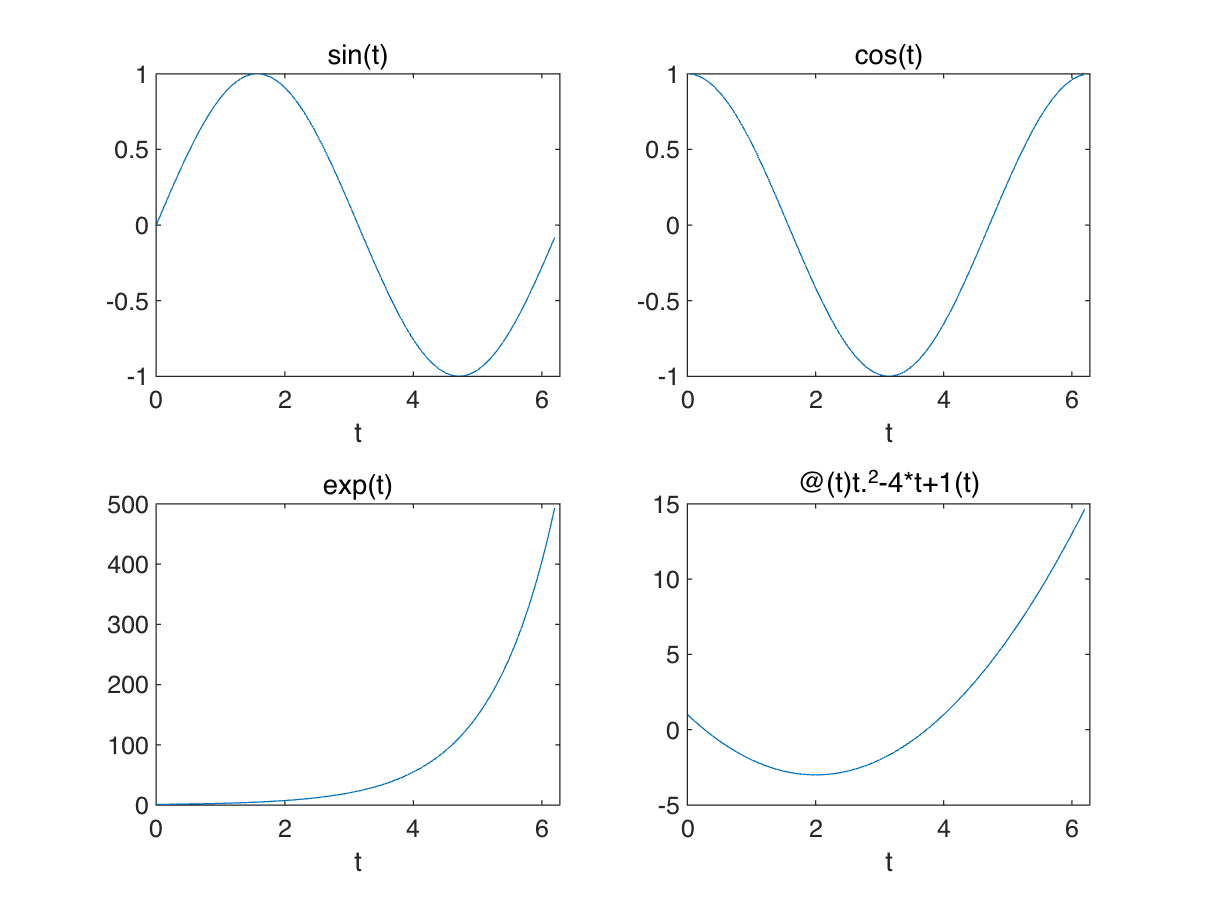

    xlabel('t');
    title([func2str(fh{n}),'(t)']);
    set(gca,'XLim',[0,2*pi]);
end